# 3D Matrix Creation for Slow Micro-CTD Data

## Load Data File for transects


% pfile = 'data_pandcfg/data_0007.p';
 cfg_result = extract_setupstr(pfile);
 %cfg_result = 'data_0004.cfg';
% %Convert to Physical Units
  %data = odas_p2mat(pfile,'vehicle','vmp','profile_dir','down');  %vmp downward profile
 %data = odas_p2mat(pfile,'constant_temp', 'T1_fast');  
data = odas_p2mat(pfile);

%-------------------PATCH, RUN ONCE---------------------
% Patch file to change to vmp and downward (only done for data_004.p so far)

Returning data from existing MAT-file: /Users/jotri/Documents/MATLAB/odas/data_pandcfg/data_0007.mat


No bad records were found in file /Users/jotri/Documents/MATLAB/odas/data_pandcfg/data_0007.p

Address Matrix:
   0   0   1   2   5   7   8   9
  32  40   1   2   5   7   8   9
  41  42   1   2   5   7   8   9
   4   6   1   2   5   7   8   9
  10  11   1   2   5   7   8   9
  12  48   1   2   5   7   8   9
   0  49   1   2   5   7   8   9
   0  50   1   2   5   7   8   9

     channel:  0 = Gnd
     channel:  1 = Ax
     channel:  2 = Ay
     channel:  4 = T1
     channel:  5 = T1_dT1
     channel:  6 = T2
     channel:  7 = T2_dT2
     channel:  8 = sh1
     channel:  9 = sh2
     channel: 10 = P
     channel: 11 = P_dP
     channel: 12 = PV
     channel: 32 = V_Bat
     channel: 40 = Incl_Y
     channel: 41 = Incl_X
     channel: 42 = Incl_T
even channel: 48 = JAC_C
 odd channel: 49 = JAC_C
     channel: 50 = JAC_T


% setup = extract_setupstr(pfile,'setup.cfg');   %extracts setup file named setup.cfg for editing (correct from rvmp (up) to vmp (down))
% 
%  cal_info = cal_FP07_in_situ;
%  cal_info.profile_min_W = 0.5; %per code provided - note different from profiles below
%  cal_info.order = 1; 
%  filename = [pfile(1:end-2) '.mat'];
%  diss = quick_look(pfile,[],[]); close all
%  for p=1:diss.profiles_in_this_file
%      [T0_1(p),b_T1(p),lags_T1(p)]=cal_FP07_in_situ(filename,'JAC_T','T1','T2655',...
%          cal_info,'profile_num',p,'make_figures',false)
%  end
%  T0_T1 = mean(T0_1);
%  beta_T1=mean(b_T1);
%  % -->  add to setup_corrected.cfg manually
% 

  patch_setupstr(pfile,'data_pandcfg/data_0007.cfg')
%-------------------------------------------------------

%TIMES ARE IN UTC ON INSTRUMENT - NEED TO CONVERT TO LOCAL TIME

%Pressure and Profile Identification
pMin = 1.5;   %Min pressure (dbar)
wMin = 0.6;   %Min dP/dt = vertical velocity if diff(P) since dt = 1 s (dbar/s)
minDuration = 10;   %Minimum duration (s)
% [P records] = show_P(pfile);     
% dP_dt = gradient(P_slow,1/fs_slow);

figure(100), subplot(2,1,1), hold on, plot(data.t_slow, data.P_slow,'b'), grid on; set(gca,'ydir','rev'), xlabel('Time [s]'), ylabel('P [dbar]')
ind_profile_slow = get_profile(data.P_slow, data.W_slow, pMin, wMin, 'down', minDuration, data.fs_slow);

## Load Data

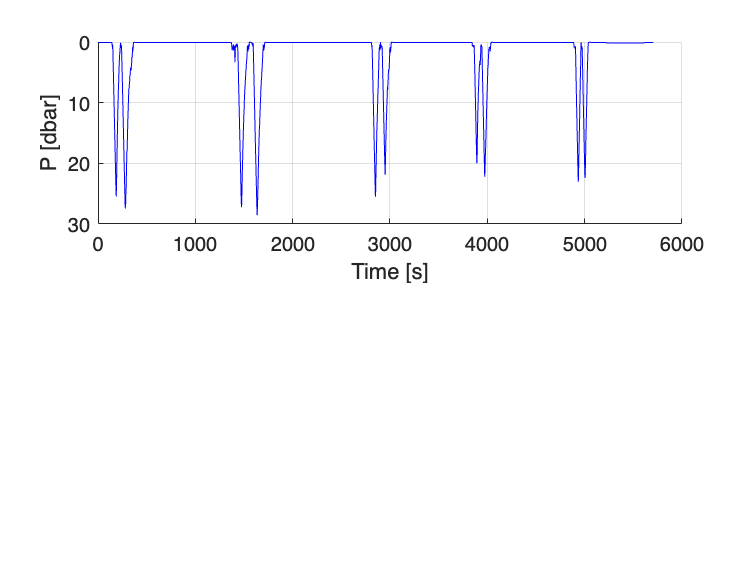


% Load the raw profile data (change file number as needed)

load('data_0007.mat');

%defining input variables
T = JAC_T;
P_cvt = convert_odas(P,'P',setupfilestr); % Convert raw pressure
S = salinity(P_cvt,JAC_T,JAC_C); % Calculate salinity from CTD
P = 1.5:.5:40 % Define pressure bins
data_file_num = 7; % Index of the data file/transect
ncfilename = 'SUBFEX24-uCTD-binavg-slow-0019-C.nc'; % NC file name

%Create arrays to use in tempcompmatrix and salinitiesmatrix
% Initialize cell arrays to hold the profiles

P =     1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000   25.0000   25.5000   26.0000


temperature_values_profiles = cell(1, length(ind_profile_slow));
pressure_values_profiles = cell(1, length(ind_profile_slow));
salinity_values_profiles = cell(1, length(ind_profile_slow));

% Loop over profiles to store data
k = 1; 
for i = 1:length(ind_profile_slow)
    temperature_values = T(ind_profile_slow(1,i):ind_profile_slow(2,i));
    pressure_values = P_cvt(ind_profile_slow(1,i):ind_profile_slow(2,i));
    salinity_values = S(ind_profile_slow(1,i):ind_profile_slow(2,i));

    % Store the entire temperature and pressure profiles in cell arrays
    temperature_values_profiles{k} = temperature_values; 
    pressure_values_profiles{k} = pressure_values; 
    salinity_values_profiles{k} = salinity_values;
    
    k = k + 1;
end

## Create 1D Variable Matrices (Bin Averaged)


% Create temperature and salinity matrices averaged over pressure bins

thetempcompmatrix = tempcompmatrix(pressure_values_profiles,temperature_values_profiles,setupfilestr, fs_fast,pMin, .5);

Dataset 1: Depth range in data: 1.50 to 30.54 dbar
Dataset 1: Depth: 1.500000e+00 dbar, Average Temperature: 13.49°C
Dataset 1: Depth: 2 dbar, Average Temperature: 13.50°C
Dataset 1: Depth: 2.500000e+00 dbar, Average Temperature: 13.51°C
Dataset 1: Depth: 3 dbar, Average Temperature: 13.51°C
Dataset 1: Depth: 3.500000e+00 dbar, Average Temperature: 13.49°C
Dataset 1: Depth: 4 dbar, Average Temperature: 13.48°C
Dataset 1: Depth: 4.500000e+00 dbar, Average Temperature: 13.48°C
Dataset 1: Depth: 5 dbar, Average Temperature: 13.45°C
Dataset 1: Depth: 5.500000e+00 dbar, Average Temperature: 13.42°C
Dataset 1: Depth: 6 dbar, Average Temperature: 13.37°C
Dataset 1: Depth: 6.500000e+00 dbar, Average Temperature: 13.34°C
Dataset 1: Depth: 7 dbar, Average Temperature: 13.30°C
Dataset 1: Depth: 7.500000e+00 dbar, Average Temperature: 13.04°C
Dataset 1: Depth: 8 dbar, Average Temperature: 12.71°C
Dataset 1: Depth: 8.500000e+00 dbar, Average Temperature: 12.53°C
Dataset 1: Depth: 9 dbar, Average Te

thesalinitymatrix = salinitiesmatrix(pressure_values_profiles,salinity_values_profiles,setupfilestr, fs_fast,pMin, .5);

Dataset 1: Depth range in data: 1.50 to 30.54 dbar
Dataset 1: Depth: 1.500000e+00 dbar, Average Salinity: 33.87
Dataset 1: Depth: 2 dbar, Average Salinity: 33.86
Dataset 1: Depth: 2.500000e+00 dbar, Average Salinity: 33.86
Dataset 1: Depth: 3 dbar, Average Salinity: 33.86
Dataset 1: Depth: 3.500000e+00 dbar, Average Salinity: 33.86
Dataset 1: Depth: 4 dbar, Average Salinity: 33.86
Dataset 1: Depth: 4.500000e+00 dbar, Average Salinity: 33.85
Dataset 1: Depth: 5 dbar, Average Salinity: 33.84
Dataset 1: Depth: 5.500000e+00 dbar, Average Salinity: 33.85
Dataset 1: Depth: 6 dbar, Average Salinity: 33.85
Dataset 1: Depth: 6.500000e+00 dbar, Average Salinity: 33.87
Dataset 1: Depth: 7 dbar, Average Salinity: 33.82
Dataset 1: Depth: 7.500000e+00 dbar, Average Salinity: 33.79
Dataset 1: Depth: 8 dbar, Average Salinity: 33.84
Dataset 1: Depth: 8.500000e+00 dbar, Average Salinity: 33.86
Dataset 1: Depth: 9 dbar, Average Salinity: 33.79
Dataset 1: Depth: 9.500000e+00 dbar, Average Salinity: 33.75


temperature_matrix = thetempcompmatrix'

temperature_matrix =    13.4945   13.5636   14.3076   14.4020   15.1188   15.1297   15.6579   15.6970   15.7677   16.4026
   13.5042   13.5632   14.3089   14.4043   15.1373   15.0733   15.6711   15.8399   15.9618   16.4653
   13.5128   13.5592   14.3072   14.3801   15.1364   15.0102   15.5624   15.9058   15.9194   16.3142
   13.5097   13.5556   14.2806   14.2788   15.1413   14.8731   14.8525   15.7886   15.7567   16.0597
   13.4946   13.5379   14.2657   14.0507   15.1510   14.6101   13.6475   15.3541   15.5254   15.7081
   13.4846   13.5309   14.1986   13.7967   15.0755   13.7012   13.0298   14.1420   15.1334   15.4095
   13.4751   13.5485   14.0463   13.5759   14.5041   12.5363   12.9813   13.1429   14.3711   15.0941
   13.4453   13.5668   13.8445   13.2421   13.1505   12.0099   12.9535   12.9991   13.6331   14.4322
   13.4199   13.5637   13.6302   12.9497   12.0837   11.9087   12.8867   12.9502   13.2977   13.6942
   13.3678   13.5546   13.3297   12.6851   11.8754   11.8589   12.7810

salinity_matrix = thesalinitymatrix'

salinity_matrix =    33.8653   33.8566   33.8550   33.8524   33.8488   33.8214   33.8589   33.8498   33.8833   33.8971
   33.8619   33.8551   33.8550   33.8550   33.8437   33.8197   33.8499   33.8583   33.8566   33.8370
   33.8580   33.8580   33.8496   33.8375   33.8434   33.8084   33.7769   33.8296   33.8180   33.7974
   33.8571   33.8533   33.8517   33.8225   33.8439   33.8188   33.6210   33.7911   33.8137   33.7716
   33.8562   33.8545   33.8455   33.7995   33.8459   33.7874   33.6948   33.6619   33.7989   33.7639
   33.8581   33.8631   33.8155   33.8177   33.8050   33.6323   33.8707   33.6523   33.7091   33.7913
   33.8467   33.8637   33.8025   33.8046   33.6439   33.6930   33.8846   33.8201   33.6460   33.7307
   33.8435   33.8603   33.8093   33.7838   33.6473   33.8630   33.8634   33.8817   33.7398   33.6465
   33.8469   33.8565   33.8045   33.8182   33.8299   33.8744   33.8464   33.8670   33.8285   33.7190
   33.8487   33.8574   33.7796   33.8185   33.8897   33.8746   33.8363   

## Compute GSW Variables

% Prepare pressure matrix
Prep = repmat(P',1,size(salinity_matrix, 2));

% Convert to Absolute Salinity and Conservative Temperature
SA = gsw_SA_from_SP(salinity_matrix,Prep,-120.7, 35.1);
CT = gsw_CT_from_t(SA,temperature_matrix,Prep);

% Calculate density and sigma0
rho_matrix = gsw_rho(SA,CT,Prep);
sigma_0_matrix = gsw_rho(SA,CT,0);
abs_salinity_matrix = SA 

abs_salinity_matrix =    34.0255   34.0167   34.0151   34.0125   34.0089   33.9814   34.0191   34.0099   34.0435   34.0575
   34.0220   34.0152   34.0151   34.0152   34.0038   33.9797   34.0100   34.0185   34.0168   33.9970
   34.0181   34.0182   34.0097   33.9975   34.0034   33.9684   33.9367   33.9896   33.9780   33.9572
   34.0173   34.0135   34.0118   33.9825   34.0040   33.9788   33.7801   33.9509   33.9737   33.9313
   34.0164   34.0147   34.0056   33.9594   34.0060   33.9473   33.8542   33.8211   33.9587   33.9236
   34.0182   34.0233   33.9754   33.9777   33.9649   33.7913   34.0309   33.8114   33.8686   33.9512
   34.0068   34.0239   33.9624   33.9645   33.8031   33.8523   34.0449   33.9800   33.8051   33.8903
   34.0036   34.0205   33.9692   33.9436   33.8065   34.0231   34.0235   34.0420   33.8994   33.8057
   34.0070   34.0167   33.9644   33.9781   33.9899   34.0346   34.0065   34.0272   33.9885   33.8785
   34.0088   34.0176   33.9394   33.9785   34.0500   34.0348   33.996

## Calculate Bouyancy Frequency


% Preallocate dSigma_0 and dRho
[nRows, nCols] = size(sigma_0_matrix);
dSigma_0 = zeros(nRows, nCols);
dRho = zeros(nRows, nCols);
dN = zeros(nRows, nCols);
dNtwo = zeros(nRows, nCols);

% Forward Difference at the beginning
dSigma_0(1, :) = (sigma_0_matrix(2, :) - sigma_0_matrix(1, :)) ./ (Prep(2, :) - Prep(1, :));
dRho(1, :) = (rho_matrix(2, :) - rho_matrix(1, :)) ./ (Prep(2, :) - Prep(1, :));
dN(1, :) = sqrt((9.81 ./ rho_matrix(1, :)) .* dSigma_0(1, :)) ./ ((Prep(2, :) - Prep(1, :)));
dNtwo(1,:) = (9.81 ./ rho_matrix(1, :)) .* (dSigma_0(1, :) ./ (Prep(2, :) - Prep(1, :)));

% Central Difference for the middle rows
dSigma_0(2:end-1, :) = (sigma_0_matrix(3:end, :) - sigma_0_matrix(1:end-2, :)) ./ (Prep(3:end, :) - Prep(1:end-2, :));
dRho(2:end-1, :) = (rho_matrix(3:end, :) - rho_matrix(1:end-2, :)) ./ (Prep(3:end, :) - Prep(1:end-2, :));
dN(2:end-1,:) = sqrt((9.81 ./ rho_matrix(2:end-1, :)) .* (dSigma_0(2:end-1, :) ./ (Prep(3:end, :) - Prep(1:end-2, :))));
dNtwo(2:end-1,:) = (9.81 ./ rho_matrix(2:end-1, :)) .* (dSigma_0(2:end-1, :) ./ (Prep(3:end, :) - Prep(1:end-2, :)));


% Backward Difference at the end
dSigma_0(end, :) = (sigma_0_matrix(end, :) - sigma_0_matrix(end-1, :)) ./ (Prep(end, :) - Prep(end-1, :));
dRho(end, :) = (rho_matrix(end, :) - rho_matrix(end-1, :)) ./ (Prep(end, :) - Prep(end-1, :));
dN(end, :) = sqrt((9.81 ./ rho_matrix(end, :)) .* dSigma_0(end, :)) ./ ((Prep(end, :) - Prep(end-1, :)));
dNtwo(end,:) = (9.81 ./ rho_matrix(end, :)) .* (dSigma_0(end, :) ./ (Prep(end, :) - Prep(end-1, :)));


dNtwo =    -0.0002   -0.0000   -0.0000    0.0001   -0.0003    0.0004   -0.0004   -0.0010   -0.0025   -0.0023
   -0.0001    0.0000   -0.0000   -0.0001   -0.0001    0.0002   -0.0004   -0.0006   -0.0008   -0.0005
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0004    0.0000   -0.0004    0.0001    0.0004
    0.0000    0.0000    0.0001    0.0004   -0.0000    0.0007    0.0033   -0.0001    0.0007    0.0011
    0.0001    0.0001   -0.0001    0.0009   -0.0001    0.0010    0.0055    0.0024    0.0006    0.0015
   -0.0000    0.0000    0.0001    0.0010   -0.0002    0.0033    0.0027    0.0056    0.0013    0.0011
   -0.0000   -0.0001    0.0007    0.0008    0.0027    0.0049    0.0001    0.0039    0.0033    0.0010
    0.0001   -0.0001    0.0008    0.0013    0.0060    0.0025   -0.0001    0.0007    0.0035    0.0027
    0.0002    0.0000    0.0008    0.0013    0.0042    0.0004    0.0001    0.0000    0.0018    0.0035
    0.0003    0.0000    0.0010    0.0010    0.0009    0.0002    0.0003    0.0001   

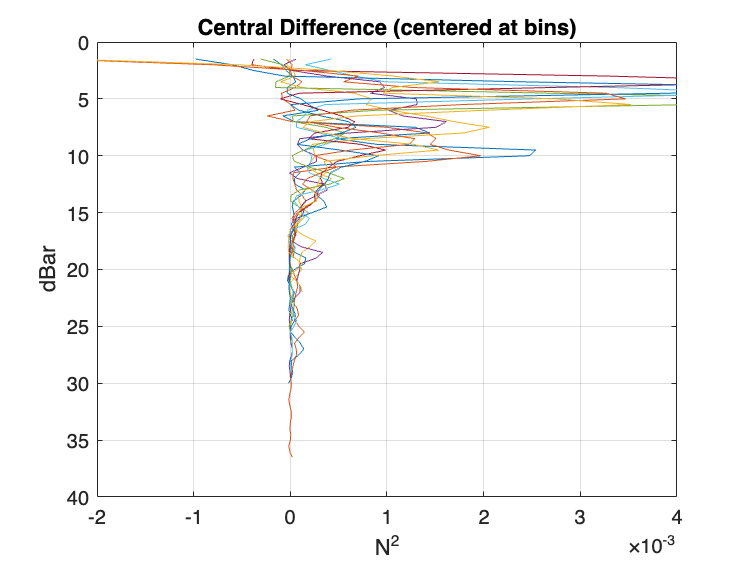

% Prep matrix adjustment
Preptwo = Prep(1:end, :);
figure;
plot(dNtwo, Preptwo);
set(gca, 'YDir', 'reverse');  % Reverse the y-axis
grid on;
xlabel('N^2');
ylabel('dBar');
title('Central Difference (centered at bins)')
xlim([-2*10^-3, 4*10^-3]);  % Set x-axis limits
hold off;

## Define Station Numbers and Transect Info

% Assign station numbers and transect line based on data file number

if data_file_num == 4
        pfile = 'data_0004.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7]; oline = 'D';  %line D
elseif data_file_num == 5
        pfile = 'data_0005.p'; station_number = [1,1,2,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9]; oline = 'C'; %line C
elseif data_file_num == 6
        pfile = 'data_0006.p'; station_number = [1,1,2,2,2,3,3,4,4,5,5,6,6,7,7]; oline = 'D'; %line D
elseif data_file_num == 7
        pfile = 'data_0007.p'; station_number = [1,1,3,3,5,5,7,7,9,9];   oline = 'C';       %line C
elseif data_file_num == 8
        pfile = 'data_0008.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9]; oline = 'C'; %line C
elseif data_file_num == 9
        pfile = 'data_0009.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9]; oline = 'C'; %line C
elseif data_file_num == 10
        pfile = 'data_0010.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9]; oline = 'C'; %line C
elseif data_file_num == 11
        pfile = 'data_0011.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9];  oline = 'C';%line C
elseif data_file_num == 12
        pfile = 'data_0012.p'; station_number = [2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9];  oline = 'C';%line C
elseif data_file_num == 13
        pfile = 'data_0013.p'; station_number = [1,1,2,2,3,3,3,4,4,5,5,6,6,7,7,8,8,9,9]; oline = 'C'; %line C
elseif data_file_num == 14
        pfile = 'data_0014.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9];  oline = 'C';%line C
elseif data_file_num == 15
        pfile = 'data_0015.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9];  oline = 'C';%line C
elseif data_file_num == 16
        pfile = 'data_0016.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9]; oline = 'C'; %line C
elseif data_file_num == 17
        pfile = 'data_0017.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9]; oline = 'C'; %line C
elseif data_file_num == 18
        pfile = 'data_0018.p'; station_number = [1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9];  oline = 'C';%line C
elseif data_file_num == 19
        pfile = 'data_0019.p'; station_number = [1,1,3,3,5,5,7,7,9,9];  oline = 'C';%line C
end



## Compute Profile Repeats (1st, 2nd cast at each station, etc.)

     1     2     1     2     1     2     1     2     1     2



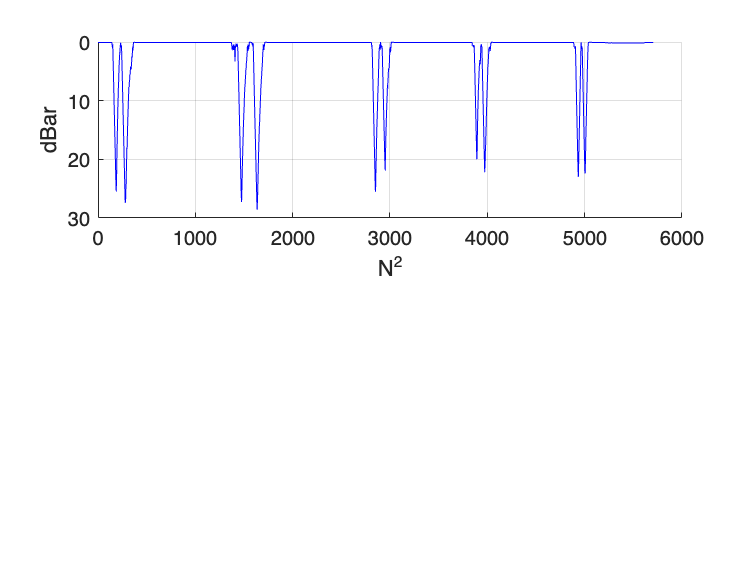


%  Preallocate profile repeat array
profile_number = zeros(size(station_number));
counts = zeros(max(station_number), 1);

% Loop through the array to assign repeat numbers
for i = 1:length(station_number)
    counts(station_number(i)) = counts(station_number(i)) + 1;
    profile_number(i) = counts(station_number(i));
end

% Display the result
disp(profile_number) % output ex.= [1,2,1,2,3,1,2,1,2,1,2,1,2,1,2]

## Create 3D Matrices

% Dimensions (using one of the input matrices to define shape)
numSlices = max(profile_number);       % Z-dimension (profiles)


(:,:,1) =

   13.4945       NaN   14.3076       NaN   15.1188       NaN   15.6579       NaN   15.7677
   13.5042       NaN   14.3089       NaN   15.1373       NaN   15.6711       NaN   15.9618
   13.5128       NaN   14.3072       NaN   15.1364       NaN   15.5624       NaN   15.9194
   13.5097       NaN   14.2806       NaN   15.1413       NaN   14.8525       NaN   15.7567
   13.4946       NaN   14.2657       NaN   15.1510       NaN   13.6475       NaN   15.5254
   13.4846       NaN   14.1986       NaN   15.0755       NaN   13.0298       NaN   15.1334
   13.4751       NaN   14.0463       NaN   14.5041       NaN   12.9813       NaN   14.3711
   13.4453       NaN   13.8445       NaN   13.1505       NaN   12.9535       NaN   13.6331
   13.4199       NaN   13.6302       NaN   12.0837       NaN   12.8867       NaN   13.2977
   13.3678       NaN   13.3297       NaN   11.8754       NaN   12.7810       NaN   13.1514
   13.3412       NaN   12.9171       NaN   11.8142       NaN   12.6298       N


(:,:,1) =

   33.8653       NaN   33.8550       NaN   33.8488       NaN   33.8589       NaN   33.8833
   33.8619       NaN   33.8550       NaN   33.8437       NaN   33.8499       NaN   33.8566
   33.8580       NaN   33.8496       NaN   33.8434       NaN   33.7769       NaN   33.8180
   33.8571       NaN   33.8517       NaN   33.8439       NaN   33.6210       NaN   33.8137
   33.8562       NaN   33.8455       NaN   33.8459       NaN   33.6948       NaN   33.7989
   33.8581       NaN   33.8155       NaN   33.8050       NaN   33.8707       NaN   33.7091
   33.8467       NaN   33.8025       NaN   33.6439       NaN   33.8846       NaN   33.6460
   33.8435       NaN   33.8093       NaN   33.6473       NaN   33.8634       NaN   33.7398
   33.8469       NaN   33.8045       NaN   33.8299       NaN   33.8464       NaN   33.8285
   33.8487       NaN   33.7796       NaN   33.8897       NaN   33.8363       NaN   33.8538
   33.8656       NaN   33.7595       NaN   33.8844       NaN   33.8262       N


(:,:,1) =

   34.0255       NaN   34.0151       NaN   34.0089       NaN   34.0191       NaN   34.0435
   34.0220       NaN   34.0151       NaN   34.0038       NaN   34.0100       NaN   34.0168
   34.0181       NaN   34.0097       NaN   34.0034       NaN   33.9367       NaN   33.9780
   34.0173       NaN   34.0118       NaN   34.0040       NaN   33.7801       NaN   33.9737
   34.0164       NaN   34.0056       NaN   34.0060       NaN   33.8542       NaN   33.9587
   34.0182       NaN   33.9754       NaN   33.9649       NaN   34.0309       NaN   33.8686
   34.0068       NaN   33.9624       NaN   33.8031       NaN   34.0449       NaN   33.8051
   34.0036       NaN   33.9692       NaN   33.8065       NaN   34.0235       NaN   33.8994
   34.0070       NaN   33.9644       NaN   33.9899       NaN   34.0065       NaN   33.9885
   34.0088       NaN   33.9394       NaN   34.0500       NaN   33.9963       NaN   34.0140
   34.0258       NaN   33.9192       NaN   34.0447       NaN   33.9862       N


(:,:,1) =

   1.0e+03 *

    1.0254       NaN    1.0252       NaN    1.0251       NaN    1.0250       NaN    1.0250
    1.0254       NaN    1.0253       NaN    1.0251       NaN    1.0250       NaN    1.0249
    1.0254       NaN    1.0252       NaN    1.0251       NaN    1.0249       NaN    1.0249
    1.0254       NaN    1.0253       NaN    1.0251       NaN    1.0250       NaN    1.0249
    1.0254       NaN    1.0253       NaN    1.0251       NaN    1.0253       NaN    1.0250
    1.0254       NaN    1.0253       NaN    1.0251       NaN    1.0255       NaN    1.0250
    1.0254       NaN    1.0253       NaN    1.0251       NaN    1.0256       NaN    1.0251
    1.0254       NaN    1.0253       NaN    1.0253       NaN    1.0255       NaN    1.0253
    1.0254       NaN    1.0254       NaN    1.0257       NaN    1.0256       NaN    1.0255
    1.0255       NaN    1.0254       NaN    1.0258       NaN    1.0256       NaN    1.0255
    1.0255       NaN    1.0255       NaN    1.0258       NaN    


(:,:,1) =

   1.0e+03 *

    1.0254       NaN    1.0252       NaN    1.0251       NaN    1.0250       NaN    1.0249
    1.0254       NaN    1.0252       NaN    1.0251       NaN    1.0249       NaN    1.0249
    1.0254       NaN    1.0252       NaN    1.0251       NaN    1.0249       NaN    1.0249
    1.0254       NaN    1.0252       NaN    1.0251       NaN    1.0249       NaN    1.0249
    1.0254       NaN    1.0252       NaN    1.0251       NaN    1.0253       NaN    1.0249
    1.0254       NaN    1.0252       NaN    1.0250       NaN    1.0255       NaN    1.0250
    1.0254       NaN    1.0253       NaN    1.0250       NaN    1.0255       NaN    1.0251
    1.0254       NaN    1.0253       NaN    1.0253       NaN    1.0255       NaN    1.0253
    1.0254       NaN    1.0253       NaN    1.0257       NaN    1.0255       NaN    1.0254
    1.0254       NaN    1.0254       NaN    1.0258       NaN    1.0255       NaN    1.0255
    1.0254       NaN    1.0255       NaN    1.0258       NaN    


(:,:,1) =

   -0.0002       NaN   -0.0000       NaN   -0.0003       NaN   -0.0004       NaN   -0.0025
   -0.0001       NaN   -0.0000       NaN   -0.0001       NaN   -0.0004       NaN   -0.0008
   -0.0000       NaN    0.0000       NaN   -0.0000       NaN    0.0000       NaN    0.0001
    0.0000       NaN    0.0001       NaN   -0.0000       NaN    0.0033       NaN    0.0007
    0.0001       NaN   -0.0001       NaN   -0.0001       NaN    0.0055       NaN    0.0006
   -0.0000       NaN    0.0001       NaN   -0.0002       NaN    0.0027       NaN    0.0013
   -0.0000       NaN    0.0007       NaN    0.0027       NaN    0.0001       NaN    0.0033
    0.0001       NaN    0.0008       NaN    0.0060       NaN   -0.0001       NaN    0.0035
    0.0002       NaN    0.0008       NaN    0.0042       NaN    0.0001       NaN    0.0018
    0.0003       NaN    0.0010       NaN    0.0009       NaN    0.0003       NaN    0.0006
   -0.0001       NaN    0.0014       NaN    0.0000       NaN    0.0005       N

numCols   = max(station_number);       % X-dimension (stations)
numRows   = size(temperature_matrix, 1);  % Y-dimension (depth levels)

% Preallocate all 3D output arrays
JAC_T    = NaN(numRows, numCols, numSlices);
JAC_S    = NaN(numRows, numCols, numSlices);
SA       = NaN(numRows, numCols, numSlices);
RHO      = NaN(numRows, numCols, numSlices);
SIGMA_0  = NaN(numRows, numCols, numSlices);
Ntwo     = NaN(numRows, numCols, numSlices);

% Fill all matrices in one loop
for i = 1:length(station_number)
    col   = station_number(i);
    slice = profile_number(i);
    
    JAC_T(:, col, slice)    = temperature_matrix(:, i);
    JAC_S(:, col, slice)    = salinity_matrix(:, i);
    SA(:, col, slice)       = abs_salinity_matrix(:, i);
    RHO(:, col, slice)      = rho_matrix(:, i);
    SIGMA_0(:, col, slice)  = sigma_0_matrix(:, i);

   05-Jul-2024 23:15:02   05-Jul-2024 23:17:39   05-Jul-2024 23:46:29   05-Jul-2024 23:48:01   06-Jul-2024 00:10:20   06-Jul-2024 00:11:48   06-Jul-2024 00:33:39   06-Jul-2024 00:34:59   06-Jul-2024 00:49:18   06-Jul-2024 00:50:22
   05-Jul-2024 23:15:43   05-Jul-2024 23:18:28   05-Jul-2024 23:47:02   05-Jul-2024 23:48:40   06-Jul-2024 00:10:55   06-Jul-2024 00:12:25   06-Jul-2024 00:34:07   06-Jul-2024 00:35:32   06-Jul-2024 00:49:43   06-Jul-2024 00:50:50



    Ntwo(:, col, slice)     = dNtwo(:, i);
end

disp('JAC_T:'); disp(JAC_T);
disp('JAC_S:'); disp(JAC_S);
disp('SA:'); disp(SA);
disp('RHO:'); disp(RHO);
disp('SIGMA_0:'); disp(SIGMA_0);
disp('Ntwo:'); disp(Ntwo);


## Find start and stop times of each profile


% Convert profile index to seconds since micro-CTD was turned on
time_on = Hour*3600 + Minute*60 + Second; % time the micro-CTD was turned on in seconds
rate = channel_sampling_rate('P',setupfilestr,fs_fast);
time_profiles_sec = time_on + ((ind_profile_slow )./rate); % profile times in seconds since 00:00

% Convert seconds to duration format
durationMatrix = seconds(time_profiles_sec);

% Create base date from profile metadata
baseDate = datetime(Year, Month, Day, 0, 0, 0); 
datetimeMatrix = baseDate + durationMatrix; % Add elapsed time to base date

% Convert to datetime strings
formattedTimes = cellfun(@(dt) datestr(dt, 'mm-dd-yyyy HH:MM:SS'), num2cell(datetimeMatrix), 'UniformOutput', false);

% Convert to datetime format
profile_start_datetime = datetime(formattedTimes,'InputFormat','MM-dd-yyyy HH:mm:ss');
disp(profile_start_datetime);

station_latitude =    35.1184
   35.1217
   35.1246
   35.1275
   35.1305
   35.1339
   35.1368
   35.1393
   35.1425


station_longitude =  -120.7436
 -120.7391
 -120.7352
 -120.7311
 -120.7271
 -120.7223
 -120.7185
 -120.7151
 -120.7108


## Planned Station Coordinates

% Line C station lat/lon coordinates

line_C_coordinates =   [35.1184, -120.7436;
                        35.1217, -120.7391;
                        35.1246, -120.7352;
                        35.1275, -120.7311;
                        35.1305, -120.7271;
                        35.1339, -120.7223;
                        35.1368, -120.7185;
                        35.1393, -120.7151;

         0
    1.0014
    1.4943
    2.0014
    2.5023
    3.5104
    4.0039



         0
    0.5497
    1.0291
    1.5219
    2.0155
    2.5929
    3.0654
    3.4812
    4.0098



                        35.1425, -120.7108]  ;

% Line D station lat/lon coordinates
line_D_coordinates =   [35.1125, -120.7223;
                        35.1186, -120.7142;
                        35.1215, -120.7101;

time_ship = 78650×1 int64 column vector
     0
    15
    30
    45
    60
    75
    90
   105
   120
   135


                        35.1245, -120.7059;

round_ship_times = 78650×1 int64 column vector
     0
    15
    30
    45
    60
    75
    90
   105
   120
   135


                        35.1276, -120.7019;

lat_ship =    32.7062
   32.7062
   32.7062
   32.7062
   32.7062
   32.7062
   32.7062
   32.7062
   32.7062
   32.7062


                        35.1337, -120.6937;

lon_ship =  -117.2362
 -117.2362
 -117.2362
 -117.2362
 -117.2362
 -117.2362
 -117.2362
 -117.2362
 -117.2362
 -117.2362


                        35.1367, -120.6897;];


% Find station line being used
if oline == 'C'
    line_coordinates = line_C_coordinates;
else 

round_diff_seconds =       952920      953070      954810      954900      956235      956325      957630      957720      958575      958635
      952950      953115      954840      954930      956265      956355      957660      957750      958590      958665


    line_coordinates = line_D_coordinates;

round_diff_transpose_start =       952920
      953070
      954810
      954900
      956235
      956325
      957630
      957720
      958575
      958635


end

station_latitude = line_coordinates(:,1)
station_longitude = line_coordinates (:,2)


## Find distance away from first station


% Initialize the distance array
distance_from_first_station = zeros(length(line_coordinates), 1);

% Calculate distances in km
for i = 1:length(line_coordinates)
    distance_from_first_station(i) = haversine(line_coordinates(1,:), line_coordinates(i,:));
end

disp(distance_from_first_station);


## Ship Recorded Coordinates

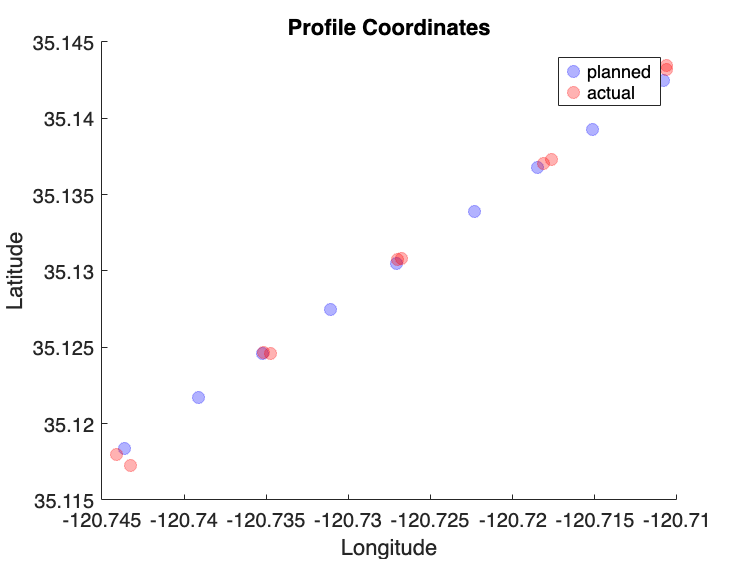

% Read shipboard time and GPS coordinates from NetCDF

time_ship = ncread('underway_met_subfex24.nc','time')
round_ship_times = round(time_ship./15).*15
lat_ship =ncread('underway_met_subfex24.nc','LA') 

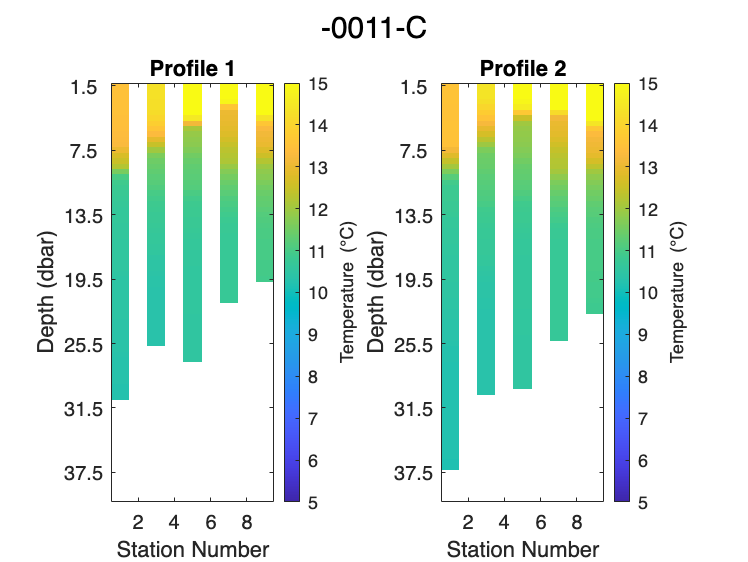

lon_ship = ncread('underway_met_subfex24.nc','LO')

% Define the reference datetime of shipboard clock
ref_time = datetime('2024-06-24 22:33:06', 'InputFormat', 'yyyy-MM-dd HH:mm:ss');

% Calculate elapsed seconds from reference time
time_diff_seconds = seconds(profile_start_datetime - ref_time);
round_diff_seconds = round(time_diff_seconds./15).*15
round_diff_transpose_start = round_diff_seconds(1,:)'

% Match each profile start time to nearest shipboard time index
[~, idx] = ismember(round_diff_transpose_start, round_ship_times);

% Extract shipboard coordinate for each profile
profile_lat = lat_ship(idx);
profile_lon = lon_ship(idx);

## Plot recorded coordinates against planned coordinates


figure;
hold on;
scatter(line_C_coordinates(:,2), line_C_coordinates(:,1), 'MarkerFaceColor','b','MarkerEdgeColor','b',...
    'MarkerFaceAlpha',.3,'MarkerEdgeAlpha',.3)
scatter (profile_lon,profile_lat, 'MarkerFaceColor','r','MarkerEdgeColor','r',...
    'MarkerFaceAlpha',.3,'MarkerEdgeAlpha',.3)
ylabel('Latitude')
xlabel('Longitude')
legend('planned','actual')
title('Profile Coordinates')
hold off;
%drawnow;

## Temperature plot

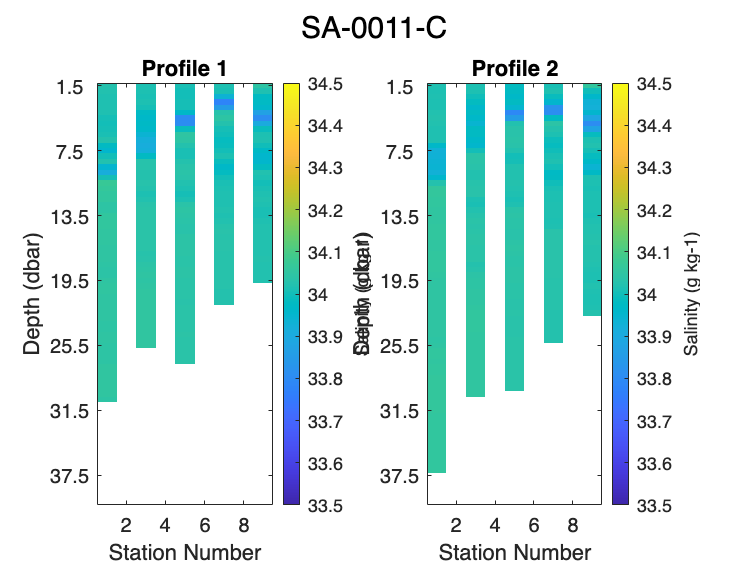



% Number of slices
numSlices = size(JAC_T, 3);


% Create a figure
figure;

sgtitle(pfile); % Overall title
% Loop through each slice
for i = 1:numSlices
    subplot(1, numSlices, i); % Create subplots for each slice

    % Mask NaN values
    mask = isnan(JAC_T(:, :, i));

    % Display the heat map for the slice
    imagesc(JAC_T(:, :, i), 'AlphaData', ~mask);       
    colorbar; hold on;                 % Add a color bar to indicate scale

    % Set color limits
    clim = [5, 15]; % Define the min and max color limits
    caxis(clim); 

    % Add contour lines
    contour(JAC_T(:, :, i), 'LineColor', 'k');

    % Title for each subplot
    title(['Profile ' num2str(i)]); 
    axis xy; % Set axis direction
    set(gca, 'YDir', 'reverse'); % Reverse y-axis direction

    % Set labels
    ylabel('Depth (dbar)');
    xlabel('Station Number');
    ylabel(colorbar, 'Temperature ({\circ}C)');

    % Set y-tick labels
    yTicks = 1.5:0.5:numRows + 1; % Calculate y-ticks
    set(gca, 'YTick', 1:numRows, 'YTickLabel', yTicks); % Set the y-ticks and labels
    tickIndices = 1:12:length(yTicks); % Select every tenth tick
    set(gca, 'YTick', tickIndices, 'YTickLabel', yTicks(tickIndices)); % Set the y-ticks and labels

  
end

## Salinity plot

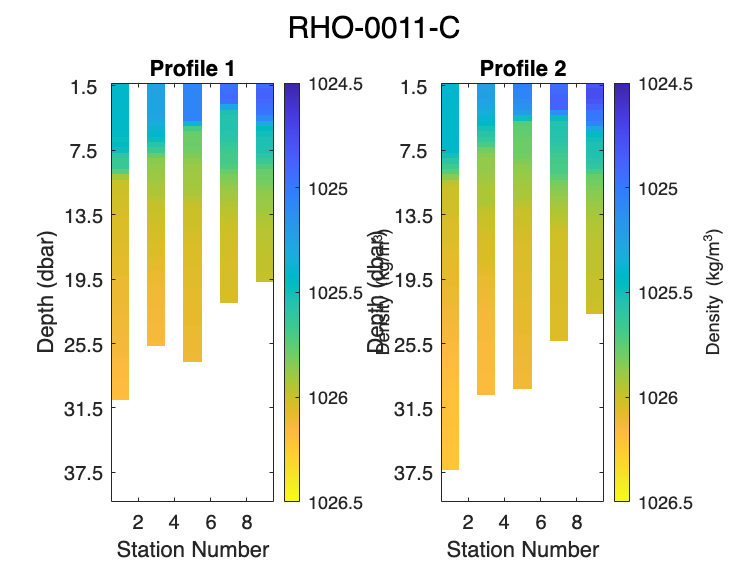



sgtitle(pfile); % Overall title

% Loop through each slice
for i = 1:numSlices
    subplot(1, numSlices, i); % Create subplots for each slice

    % Mask NaN values
    mask = isnan(SA(:, :, i));

    % Display the heat map for the slice
    imagesc(SA(:, :, i), 'AlphaData', ~mask);       
    colorbar; hold on;                 % Add a color bar to indicate scale

    % Set color limits
    clim = [33.5, 34.5]; % Define the min and max color limits
    caxis(clim); 

    % Add contour lines
    contour(SA(:, :, i), 'LineColor', 'k');

    % Title for each subplot
    title(['Profile ' num2str(i)]); 
    axis xy; % Set axis direction
    set(gca, 'YDir', 'reverse'); % Reverse y-axis direction

    % Set labels
    ylabel('Depth (dbar)');
    xlabel('Station Number');
    ylabel(colorbar, 'Salinity (g kg-1)');

    % Set y-tick labels
    yTicks = 1.5:0.5:numRows + 1; % Calculate y-ticks
    set(gca, 'YTick', 1:numRows, 'YTickLabel', yTicks); % Set the y-ticks and labels
    tickIndices = 1:12:length(yTicks); % Select every tenth tick

SIGMA_0_notes =     'Potential density calulated using gsw_sigma0 from GSW. 
      The matrix has been divided into slices by profile number. 
      e.g. The 1st profile from each station makes up the first slice, 
      the second profile from each station makes up the second slice 
      Each column represents a station.'


    set(gca, 'YTick', tickIndices, 'YTickLabel', yTicks(tickIndices)); % Set the y-ticks and labels

  
end
hold off

SA_notes =     'Absolute salinity calulated using gsw_SA_from_SP from GSW. 
      The matrix has been divided into slices by profile number. 
      e.g. The 1st profile from each station makes up the first slice, 
      the second profile from each station makes up the second slice.
      Each column represents a station.'


## Density Plot

Ntwo_notes =     'Bouyancy frequency squared, calculated with Sigma_0 as desity. 
     Central difference formula was used to find average N^2 at every half dbar.'


figure
sgtitle(pfile); % Overall title
% Loop through each slice

File_Summary_notes =     'Data collected by micro-CTD for SUBFEX project. 
     File contains temperature, pressure, salinity, and density 
     profile data. Created using ODAS library on MatLab'


for i = 1:numSlices
    subplot(1, numSlices, i); % Create subplots for each slice

    % Mask NaN values
    mask = isnan(RHO(:, :, i));

    % Display the heat map for the slice
    imagesc(RHO(:, :, i), 'AlphaData', ~mask);       

    colorbar; hold on;                 % Add a color bar to indicate scale

    % Set color limits

n_stations = 9

    clim = [1024.5, 1026.5]; % Define the min and max color limits
    caxis(clim); 


unique_profiles = 2

    % Add contour lines
    contour(RHO(:, :, i), 'LineColor', 'k');

    % Title for each subplot
    title(['Profile ' num2str(i)]); 
    axis xy; % Set axis direction
    set(gca, 'YDir', 'reverse'); % Reverse y-axis direction

    % Set labels
    ylabel('Depth (dbar)');
    xlabel('Station Number');
    hColorBar = colorbar; % Store the colorbar handle
    ylabel(hColorBar, 'Density (kg/m^3)');

    % Flip the color bar direction
    set(hColorBar, 'Direction', 'reverse');  % Flip the color bar

    % Set y-tick labels
    yTicks = 1.5:0.5:numRows + 1; % Calculate y-ticks
    set(gca, 'YTick', 1:numRows, 'YTickLabel', yTicks); % Set the y-ticks and labels
    tickIndices = 1:12:length(yTicks); % Select every tenth tick
    set(gca, 'YTick', tickIndices, 'YTickLabel', yTicks(tickIndices)); % Set the y-ticks and labels

  
end
hold off

## Descriptions for NC File Note attributes



station_distance_notes = sprintf(['Station distance from the first station in km. \n' ...
    'e.g., distance of the last station from the first is \n'...
    'the length of the entire station line.']);

profile_number_notes= sprintf(['1xn matrix containing the number of profiles taken at each \n' ...
    'station. e.g. 1 = 1st profile taken  at a station,\n'...
    ' 2 = 2nd profile taken at same station.']);

JAC_S_notes = sprintf([' The practical salinity matrix has been divided into slices by profile number. \n'... 
    ' e.g. The 1st profile from each station makes up the first slice, \n'...
    ' the second profile from each station makes up the second slice. \n' ...
    ' Each column represents a station.']);

JAC_T_notes = sprintf([' The temperature matrix has been divided into slices by profile number. \n'... 
    ' e.g. The 1st profile from each station makes up the first slice, \n'...
    ' the second profile from each station makes up the second slice. \n' ...
    ' Each column represents a station.']);

RHO_notes = sprintf([' The density matrix has been divided into slices by profile number. \n'... 
    ' e.g. The 1st profile from each station makes up the first slice, \n'...
    ' the second profile from each station makes up the second slice.\n' ...
    ' Each column represents a station.']);
SIGMA_0_notes = sprintf(['Potential density calulated using gsw_sigma0 from GSW. \n' ...
    ' The matrix has been divided into slices by profile number. \n'... 
    ' e.g. The 1st profile from each station makes up the first slice, \n'...
    ' the second profile from each station makes up the second slice \n' ...
    ' Each column represents a station.'])
SA_notes = sprintf(['Absolute salinity calulated using gsw_SA_from_SP from GSW. \n' ...
    ' The matrix has been divided into slices by profile number. \n'... 
    ' e.g. The 1st profile from each station makes up the first slice, \n'...
    ' the second profile from each station makes up the second slice.\n' ...
    ' Each column represents a station.'])
Ntwo_notes = sprintf(['Bouyancy frequency squared, calculated with Sigma_0 as desity. \n' ...
    'Central difference formula was used to find average N^2 at every half dbar.'])
File_Summary_notes = sprintf(['Data collected by micro-CTD for SUBFEX project. \n'...
    'File contains temperature, pressure, salinity, and density \n'...
    'profile data. Created using ODAS library on MatLab'])



## Create NC File



% Define the output netcdf filename
delete(ncfilename);  

% Define the number of profiles and pressure levels
n_stations = max(station_number)
n_profiles = length(station_number);  % Number of profiles
n_pressures = length(P);  % Number of pressure levels
unique_profiles = length(unique(profile_number))


% create the netcdf file using nccreate
% Pressure (1D)
nccreate(ncfilename, 'pressure', 'Dimensions', {'pressure_bins', n_pressures}, 'Datatype', 'double');

% Add attributes using ncwriteatt
ncwriteatt(ncfilename, 'pressure', 'units', 'dBar');
ncwriteatt(ncfilename, 'pressure', 'standard_name', 'sea_water_pressure');

% Convert the datetime object to a string before writing
profile_start_datetime_string = datestr(profile_start_datetime, 'mm-dd-yyyy HH:MM:SS UTC'); 
profile_start_datetime_str = profile_start_datetime_string(1:2:end, :);
profile_end_datetime_str = profile_start_datetime_string(2:2:end, :);

% Write the string (not datetime) to the NetCDF variable

NetCDF file saved as SUBFEX24-uCTD-binavg-slow-0019-C.nc


nccreate(ncfilename,'profile_start_datetime','Dimensions', {'time', n_profiles, 'characters', 23},'Datatype', 'char');
ncwriteatt(ncfilename, 'profile_start_datetime', 'long_name', 'start_time)of_profiles');
ncwriteatt(ncfilename, 'profile_start_datetime', 'units', 'mm-dd-yyyy HH:MM:SS UTC');

% Profile Coordinates and Distances (1D)
nccreate(ncfilename, 'profile_lat','Dimensions',{'total_profiles',n_profiles});
ncwriteatt(ncfilename, 'profile_lat', 'units', 'decimal_degrees_north');
ncwriteatt(ncfilename, 'profile_lat', 'long_name', 'latitude_of_profiles');
ncwriteatt(ncfilename, 'profile_lat', 'notes', 'latitude of each profile in decimal degrees. Shipboard data used.' );

nccreate(ncfilename, 'profile_lon','Dimensions',{'total_profiles',n_profiles});
ncwriteatt(ncfilename, 'profile_lon', 'units', 'decimal_degrees_east');
ncwriteatt(ncfilename, 'profile_lon', 'long_name', 'longitude_of_profiles');
ncwriteatt(ncfilename, 'profile_lon', 'notes', 'longitude of each profile in decimal degrees. Shipboard data used' );

% Profile Numbers (1D)
nccreate(ncfilename, 'profile_number','Dimensions',{'total_profiles',n_profiles});
ncwriteatt(ncfilename, 'profile_number', 'long_name', 'profiles_taken_per_station');
ncwriteatt(ncfilename, 'profile_number','notes', profile_number_notes);

% Station Profile Numbers (1D)
nccreate(ncfilename, 'station_number','Dimensions',{'total_profiles',n_profiles});
ncwriteatt(ncfilename, 'station_number', 'long_name', 'station_number');
ncwriteatt(ncfilename, 'station_number','notes',' 1xn matrix containing the station number at which each profile was taken.');

% Temperature, Salinity, and Density matrices (2D)
nccreate(ncfilename, 'JAC_S','Dimensions',{'pressure_bins',n_pressures,'total_stations',n_stations,'profiles_per_station',unique_profiles});
ncwriteatt(ncfilename, 'JAC_S', 'units', '1');
ncwriteatt(ncfilename, 'JAC_S', 'standard_name', 'sea_water_practical_salinity');
ncwriteatt(ncfilename,'JAC_S','notes', JAC_S_notes);

nccreate(ncfilename, 'JAC_T','Dimensions',{'pressure_bins',n_pressures,'total_stations',n_stations,'profiles_per_station',unique_profiles});
ncwriteatt(ncfilename, 'JAC_T', 'units', 'degrees_C');
ncwriteatt(ncfilename, 'JAC_T', 'standard_name', 'sea_water_temperature');
ncwriteatt(ncfilename,'JAC_T','notes', JAC_T_notes);

nccreate(ncfilename, 'RHO','Dimensions',{'pressure_bins',n_pressures,'total_stations',n_stations,'profiles_per_station',unique_profiles});
ncwriteatt(ncfilename, 'RHO', 'units', 'kg m-3');
ncwriteatt(ncfilename, 'RHO', 'standard_name', 'sea_water_density');
ncwriteatt(ncfilename,'RHO','notes', RHO_notes);

nccreate(ncfilename, 'SIGMA_0','Dimensions',{'pressure_bins',n_pressures,'total_stations',n_stations,'profiles_per_station',unique_profiles});
ncwriteatt(ncfilename, 'SIGMA_0', 'units', 'kg m-3');
ncwriteatt(ncfilename, 'SIGMA_0', 'standard_name', 'sea_water_potential_density');
ncwriteatt(ncfilename,'SIGMA_0','notes',SIGMA_0_notes);

nccreate(ncfilename, 'SA','Dimensions',{'pressure_bins',n_pressures,'total_stations',n_stations,'profiles_per_station',unique_profiles});
ncwriteatt(ncfilename, 'SA', 'units', 'g kg-1');
ncwriteatt(ncfilename, 'SA', 'standard_name', 'sea_water_absolute_salinity');
ncwriteatt(ncfilename,'SA','notes', SA_notes);

nccreate(ncfilename, 'Ntwo','Dimensions',{'pressure_bins',n_pressures,'total_stations',n_stations,'profiles_per_station',unique_profiles});
ncwriteatt(ncfilename, 'Ntwo', 'units','s^-1');
ncwriteatt(ncfilename, 'Ntwo','long name', 'bouyancy frequency squared');
ncwriteatt(ncfilename,'Ntwo','notes', Ntwo_notes);

%Global Variables
ncwriteatt(ncfilename,"/","modification_date",datestr(datetime("now")))
ncwriteatt(ncfilename,"/","Instrument","Micro-CTD")
ncwriteatt(ncfilename,"/","Contact","Jo Trillo, email:josephine.trillo@sjsu.edu")
ncwriteatt(ncfilename,"/","File_Summary",File_Summary_notes);

% Write data to the variables
ncwrite(ncfilename, 'pressure', P);
ncwrite(ncfilename, 'profile_start_datetime', profile_start_datetime_str);
ncwrite(ncfilename, 'profile_lat', profile_lat);
ncwrite(ncfilename, 'profile_lon', profile_lon);
ncwrite(ncfilename, 'profile_number', profile_number);
ncwrite(ncfilename, 'station_number', station_number);
ncwrite(ncfilename, 'JAC_S', JAC_S);
ncwrite(ncfilename, 'JAC_T', JAC_T);
ncwrite(ncfilename, 'RHO', RHO);
ncwrite(ncfilename, 'SIGMA_0', SIGMA_0);
ncwrite(ncfilename, 'SA', SA);
ncwrite(ncfilename, 'Ntwo', Ntwo);

disp(['NetCDF file saved as ', ncfilename]);

## Save .mat file



README = {
    'Variable Descriptions:'
    
    'ind_profile_slow:'
    '  2xn matrix containing start and stop indices for each profile, where n is the number of profiles. '
    '  Row 1 contains start indices, and row 2 contains stop indices. The minimum pressure needed for the '
    '  start of a profile is 1.5 dBar.'
    
    
    'profile_start_datetime:'
    '  2xn matrix containing start and stop times of each profile in mm-dd-yyy HH:MM:SS. UTC time.'
    
    'line_coordinates:'
    '  latitude and longitude of the line in decimal degrees.'
    
    'station_latitude:'
    '  latitude of the line in decimal degrees.'

     'station_longitude:'
    '  longitude of the line in decimal degrees.'

    'station_distance:'
    '  Distance to each station from the first station in km. e.g. distance of the last station from the '
    '  first is the length of the entire station.'
    
    'profile_number:'
    '  1xn matrix containing the station number at which each profile was taken.'
    
    'station_number:'
    '  1xn matrix containing the number of profiles taken at each station. e.g. 1 = 1st profile taken '
    '  at a station, 2 = 2nd profile taken at a station.'
    
    'JAC_S:'
    '  Temperature matrix that has been divided into slices by profile number. e.g. The 1st profile from '
    '  each station makes up the first slice, the second profile from each station makes up the second slice.'
    
    'JAC_T:'
    '  Salinity matrix that has been divided into slices by profile number. e.g. The 1st profile from '
    '  each station makes up the first slice, the second profile from each station makes up the second slice.'

     'RHO:'
    '  Density matrix that has been divided into slices by profile number. e.g. The 1st profile from '
    '  each station makes up the first slice, the second profile from each station makes up the second slice.'

     'P:'
    ' 1d pressure array containsing the pressure values that correspond to each point'
    ' for  the bin-averaged JAC_T and JAC_S.'
};

% Save to .mat file
% save('SUBFEX24-uCTD-binavg-slow-0019-C-20240705-2313.mat', 'README', ... % add your other variables here
%                      'ind_profile_slow', ...
%                      'ind_profile_times',  ...
%                      'line_coordinates', 'station_distance', ...
%                      'profile_number', ...
%                      'station_number', 'station_latitude','station_longitude',...
%                      'JAC_S','profile_start_datetime', ...
%                      'JAC_T','line','P','RHO');